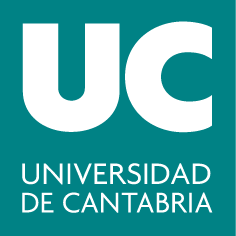

#### ***Grado en Ingeniería ****de Tecnologías de Telecomunicación*

## **G283: Cálculo II**

# **Práctica 3: Integrales triples**

*Dpto. Matemática Aplicada y Ciencias de la Computación*

### Objetivos	

- Calcular integrales triples de forma aproximada, mediante sumas de Riemann. 

- Calcular integrales triples de forma exacta, con cálculo simbólico, en coordenadas cartesianas, cilíndricas y esféricas.

- Aplicación del Teorema del Valor Medio para funciones de tres variables.

### Resumen teórico

#### Suma de Riemann

Llamamos suma de Riemann de la función $f(x,y,z)$ definida en la caja $H$ para la partición $\lbrace H_{k}\rbrace_{k=1}^{p}$ a la suma:


$$\displaystyle  \sum_{k=1}^{p} f(x_{k}, y_{k}, z_{k})\Delta V_{k} $$


donde $(x_{k},y_{k}, z_{k})$ es un punto cualquiera tomado en la subcaja $$H_{k}$$ y $\Delta V_{k}$es el volumen de  $$H_{k}$$.

Si la partición es regular con $m, n, p$ particiones en cada dirección respectivamente, entonces: $\Delta V_{k}= \Delta x \Delta y \Delta z$ con $\Delta x=\frac{x_{final}-x_{inicial}}{m}$, $\Delta y=\frac{y_{final}-y_{inicial}}{n}$, $\Delta z=\frac{z_{final}-z_{inicial}}{p}$

Si tomamos $(x_{i},y_{j}, z_{k})$ como el punto medio de cada caja:

$x_{i}=x_{inicial}+\frac{\Delta x}{2} + (i-1)\Delta x =x_{inicial}+ \Big( i - \frac{1}{2}\Big) \Delta x$     con $i=1,2,3,...,m$

$y_{j}=y_{inicial}+\frac{\Delta y}{2} + (j-1)\Delta y =y_{inicial}+ \Big( j - \frac{1}{2}\Big) \Delta y$     con $j=1,2,3,...,n$

$z_{k}=z_{inicial}+\frac{\Delta z}{2} + (k-1)\Delta z=z_{inicial}+ \Big( k- \frac{1}{2}\Big) \Delta z$        con $k=1,2,3,...,p$

#### Integral triple

Sea $f$ una función tres dos variables definida sobre una caja $H$ . Si para toda partición de $H$, tal que la norma de la partición tiende a cero ($\mid\mid R \mid \mid \rightarrow 0$, entonces el número de particiones tiende a infinito), existe el límite:


$$\displaystyle \lim_{p\to\infty} \Big( \sum_{k=1}^{p} f(x_{k}, y_{k}, z_{k})\Delta V_{k}\Big)$$


 se dice que $f$** es integrable en **$H$.

Además, el valor de este límite es la integral triple de $f$ sobre $H$ y se denota por:


$$\displaystyle \int\int\int_{H}f(x,y,z) dV=\lim_{p\to\infty} \Big( \sum_{k=1}^{p} f(x_{k}, y_{k}, z_{k})\Delta V_{k}\Big)$$


#### Coordenadas Cilíndricas

Las coordenadas cilíndricas se obtienen utilizando coordenadas polares en uno de los planos coordenados y manteniendo la tercera variable. Suponiendo que la coordenada $z$ se mantenga, las ecuaciones del cambio de cartesianas a cilíndricas serán:


$$x=rcos\theta$$
    
$$y=rsen\theta$$
    
$$z=z$$


El Jacobiano en cilíndricas es     $J=\frac{\partial (x,y,z)}{\partial(r,\theta, z)}=r$     y el elemento diferencial de volumen $dV=rdrd\theta dz$

#### Coordenadas esféricas

Las ecuaciones del cambio de cartesianas a esféricas son:


$$x=\rho sen\phi cos\theta$$
    
$$y=\rho sen\phi sen\theta$$
    
$$z=\rho cos\phi$$


El Jacobiano en esféricas es     $J=\frac{\partial (x,y,z)}{\partial(\rho, \theta, \phi)}=\rho^{2}sen\phi$    y elelemento diferencial de volumen $dV=\rho^{2}\mid sen\phi \mid d\rho d\theta d\phi$

### Comandos útiles

#### Comandos para sumar elementos de una matriz o vector

- `sum(A): `Si A es un vector suma sus componentes. Si A es una matriz, devuelve un vector fila con la suma de las filas o columnas de A especificadas. Ejemplo:

A=ones(3,3);
sum(A(1:2,:))

- `sum(A(:)):` suma todos los elementos de la matriz A. Ejemplo:

sum(A(:))

- `prod(A(:))`: multiplica todos los elementos de la matriz A. Ejemplo:

prod(A(:))

#### Comandos para calcular de forma exacta la integral triple de una función sobre un dominio cerrado y acotado

- `syms x y z`: Declara las variables simbólicas `x y z.`

- `int(int(int(f(x,y,z), z, psi1(x,y), psi2(x,y)), y, phi1(x), phi2(x)), x, a, b)`: para calcular la integral triple:


$$\int_{a}^{b}\int_{\phi_{1}(x)}^{\phi_{2}(x)}\int_{\psi_{1}(x,y)}^{\psi_{2}(x,y)} f(x,y,z) dz dy dx$$


- `double(x): `Convierte a decimal con doble precisión los valores recogidos en x, que puede ser una matriz o vector de valores. 

#### Comandos para crear una función

- `function [out1, out2, ...] = funname(in1, in2, ...)` Crea una función de nombre `funname`, con unos parámetros de entrada `(in1,in2,…) `y unas variables de salida `(out1, out2,…). `Se debe guardar la función en un fichero llamado `funname.m. `

#### Comandos para hacer ejecutable una cadena de caracteres

- `inline('expresion')`: construye una función en línea a partir de la expresión indicada. Ejemplo:

g = inline('t^2');
g(8)

- `vectorize(f):` vectoriza la fórmula de la función que aparece en el argumento de entrada.

###  Ejercicios resueltos

**1. Cálculo de integrales triples mediante sumas triples de Riemann**

a) Calcula el valor aproximado de la siguiente integral usando sumas de Riemann tomando $100^3$ cajas. 


$$\displaystyle\int_{-1}^{2}\int_{2}^{4}\int_{0}^{\pi}(x+y)e^{sen(z)}dz dy dx$$


b) Obtener el valor exacto de la integral y compararlo con el valor aproximado.

a) Calcula el valor aproximado de la siguiente integral usando sumas de Riemann tomando $100^3$ cajas. 


$$\displaystyle\int_{-1}^{2}\int_{2}^{4}\int_{0}^{\pi}(x+y)e^{sen(z)}dz dy dx$$


%Define la caja o dominio con los límites de integración
a=-1;b=2;c=2;d=4;h=0;j=pi;
%Define el número de divisiones en cada eje
m=100;n=100;p=100;
%genera incrementos
inc=[b-a,d-c,j-h]./[m,n,p];

%genera vectores con los valores de x, y, z
vx=a+inc(1)/2:inc(1):b-inc(1)/2;
vy=c+inc(2)/2:inc(2):d-inc(2)/2;
vz=h+inc(3)/2:inc(3):j-inc(3)/2;

%genera la malla con meshgrid
[X,Y,Z]=meshgrid(vx,vy,vz);

%Evalua f sobre los puntos de la malla
val=(X+Y).*exp(sin(Z));

%Calcula la suma de Riemann
format long
suma_aproximada=sum(val(:))*prod(inc)

b) Obtener el valor exacto de la integral y compararlo con el valor aproximado.

syms x y z
valor_exacto=double(int(int(int((x+y)*exp(sin(z)),x,-1,2),y,2,4),z,0,pi))
error=abs(valor_exacto-suma_aproximada)

**2. Coordenadas cilíndricas y esféricas. Cálculo de la temperatura media de un sólido.**

Se considera el sólido $H$ que ocupa la región limitada por dos paraboloides, inferiormente por $z_{2}=x^2+y^2$ y superiormente por $z_{1}=2-x^2-y^2$. 

a) Dibujar en un mismo gráfico los dos paraboloides usando coordenadas cilíndricas, considerando $r \in [0, 1]$, $\theta \in [0, 2\pi]$.

b) Calcular el volumen del sólido $H$, planteando la integral correspondiente en coordenadas cilíndricas.

c) Sabiendo que cada punto de $H$ está a una temperatura dada por $T(x,y,z)=x^2+y^2+(z-1)^2$, calcular la temperatura media de $H$ y dibujar el lugar geométrico donde se alcanza la temperatura media.

a) Dibujar en un mismo gráfico los dos paraboloides usando coordenadas cilíndricas, considerando $r \in [0, 1]$, $\theta \in [0, 2\pi]$.

En primer lugar, expresamos los dos paraboloides que limitan $H$ en coordenadas cilíndricas:


$$z_{1}=r^{2}cos^{2}\theta + r^{2}sen^{2}\theta =r^2$$



$$z_{2}= 2- r^{2}cos^{2}\theta -r^{2}sen^{2}\theta=2-r^2$$


Esos paraboloides se cortan en $r^{2}=2- r^{2} \Rightarrow 2r^{2}=2 \Rightarrow r=1$, es decir, en la circunferencia de radio 1 centrada en $(0,0,1)$, pues $z=1$ para ese radio.

Por lo tanto, se define el dominio en cilíndricas: $H= \lbrace (r,\theta, z) /0\leq \theta \leq 2\pi, 0\leq r \leq 1, r^{2} \leq z \leq 2-r^{2} \rbrace$

%Define el vector de valores del parámetro r de cilíndricas
r=linspace(0,1,20);
%Define el vector de valores del ángulo theta de cilíndricas
t=linspace(0,2*pi,40); 
%Genera la malla con las coordenadas cilíndricas (R,T) de los nudos
[R,T]=meshgrid(r,t); 
%Ecuaciones paramétricas de los paraboloides z1=2-x^2-y^2, z2=x^2+y^2
X=R.*cos(T); Y=R.*sin(T);  Z1=2-R.^2; Z2=R.^2; 
%Dibuja el paraboloide superior con transparencia 0.4 y retícula blanca
h1=surf(X,Y,Z1);
set(h1,'FaceAlpha',0.4, 'EdgeColor','w')
shading interp
hold on
%Dibuja el paraboloide inferior con transparencia 0.4 y retícula blanca
h2=surf(X,Y,Z2);
set(h2,'FaceAlpha',0.4, 'EdgeColor','w')
shading interp
axis equal
colorbar
xlabel('X'); ylabel('Y'); zlabel('Z')

b) Calcular el volumen del sólido $H$, planteando la integral correspondiente en coordenadas cilíndricas.

Considerando el dominio $H= \lbrace (r,\theta, z) /0\leq \theta \leq 2\pi, 0\leq r \leq 1, r^{2} \leq z \leq 2-r^{2} \rbrace$ y el Jacobiano en cilíndricas, la integral que hay que calcular es:


$$\text{Volumen}=\int_{0}^{2\pi}\int_{0}^{1}\int_{r^{2}}^{2-r^{2}} r dz dr d\theta$$


syms r t z
volumen=int(int(int(r,z,r^2,2-r^2),r,0,1),t,0,2*pi)

c) Sabiendo que cada punto de $H$ está a una temperatura dada por $T(x,y,z)=x^2+y^2+(z-1)^2$, calcular la temperatura media de $H$ y dibujar el lugar geométrico donde se alcanza la temperatura media.

Usando el cambio a cilíndricas, la temperatura será: $T(r,\theta, z)=r^{2}cos^{2}\theta +r^{2}sen^{2}\theta + (z-1)^{2}=r^{2}+(z-1)^{2}$

Por lo tanto, la temperatura media será: $\text{Temperatura Media}=\displaystyle\frac{\int_{0}^{2\pi}\int_{0}^{1}\int_{r^{2}}^{2-r^{2}} \Big(r^{2}+ (z-1)^{2} \Big)r dz dr d\theta}{\text{Volumen}}$

Tmedia=int(int(int((r^2+(z-1)^2)*r,z,r^2,2-r^2),r,0,1),t,0,2*pi)/volumen

El lugar geométrico donde se alcanza esa temperatura media es: $T(x,y,z)=\frac{1}{2} \Rightarrow x^{2}+y^{2}+(z-1)^{2}=\frac{1}{2}$

que es la esfera de centro $(0,0,1)$ y radio $\frac{1}{\sqrt{2}}$ (resulta más conveniente representarla en coordenadas esféricas).

%Define el vector de valores del ángulo theta de esféricas
t=0:pi/30:2*pi;
%Define el vector de valores del ángulo fi de esféricas
fi=0:pi/30:pi; 
%Genera la malla con las coordenadas esféricas (T,FI) de los nudos
[T,FI]=meshgrid(t,fi); 
%Escribe las ecuaciones paramétricas de la esfera de centro (0,0,1) y radio R=1/sqrt(2)
X= sqrt(1/2)*sin(FI).*cos(T);   
Y= sqrt(1/2)*sin(FI).*sin(T); 
Z=1+ sqrt(1/2)*cos(FI);  % centro desplazado: z=z0+ rho*cos(fi)
%Dibuja la esfera en color negro, con transparencia 0.4
h3=surf(X,Y,Z);
set(h3,'FaceAlpha',0.4,'FaceColor','k')
title('Paraboloides y esfera en su interior')
hold off